T = readtable("g_edges.csv")

T = 549×4 table
         Source           Target       Weight    Season
    ________________    ___________    ______    ______

    {'NED'         }    {'ROBERT' }     192        1   
    {'DAENERYS'    }    {'JORAH'  }     154        1   
    {'JON'         }    {'SAM'    }     121        1   
    {'LITTLEFINGER'}    {'NED'    }     107        1   
    {'NED'         }    {'VARYS'  }      96        1   
    {'DAENERYS'    }    {'DROGO'  }      91        1   
    {'ARYA'        }    {'NED'    }      90        1   
    {'CATELYN'     }    {'ROBB'   }      90        1   
    {'BRONN'       }    {'TYRION' }      86        1   
    {'CERSEI'      }    {'NED'    }      86        1   
    {'CERSEI'      }    {'ROBERT' }      80        1   
    {'LITTLEFINGER'}    {'VARYS'  }      73        1   
    {'SHAE'        }    {'TYRION' }      73        1   
    {'C

S = T.Source

S = 549×1 cell array
    {'NED'         }
    {'DAENERYS'    }
    {'JON'         }
    {'LITTLEFINGER'}
    {'NED'         }
    {'DAENERYS'    }
    {'ARYA'        }
    {'CATELYN'     }
    {'BRONN'       }
    {'CERSEI'      }
    {'CERSEI'      }
    {'LITTLEFINGER'}
    {'SHAE'        }
    {'CATELYN'     }
    {'JOFFREY'     }
    {'NED'         }
    {'DAENERYS'    }
    {'SANSA'       }
    {'TYRION'      }
    {'JEOR'        }
    {'ROBB'        }
    {'CERSEI'      }
    {'ARYA'        }
    {'BRAN'        }
    {'JAIME'       }
    {'NED'         }
    {'BRAN'        }
    {'LORAS'       }
    {'CERSEI'      }
    {'DAENERYS'    }


Tar = T.Target

Tar = 549×1 cell array
    {'ROBERT'        }
    {'JORAH'         }
    {'SAM'           }
    {'NED'           }
    {'VARYS'         }
    {'DROGO'         }
    {'NED'           }
    {'ROBB'          }
    {'TYRION'        }
    {'NED'           }
    {'ROBERT'        }
    {'VARYS'         }
    {'TYRION'        }
    {'NED'           }
    {'SANSA'         }
    {'PYCELLE'       }
    {'VISERYS'       }
    {'SEPTA_MORDANE' }
    {'TYWIN'         }
    {'JON'           }
    {'THEON'         }
    {'JOFFREY'       }
    {'SANSA'         }
    {'MAESTER_LUWIN' }
    {'NED'           }
    {'SANSA'         }
    {'ROBB'          }
    {'RENLY'         }
    {'JAIME'         }
    {'MIRRI_MAZ_DUUR'}


G = digraph(S, Tar)

G =   digraph with properties:

    Edges: [549×1 table]
    Nodes: [126×1 table]


D = indegree(G)

D =     34
    28
     1
     6
    12
    12
    11
    20
     3
     0


p = plot(G, "Layout","force")

p =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 2
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [1×126 double]
         YData: [1×126 double]
         ZData: [1×126 double]

  Show all properties


G.Nodes.NodeColors = indegree(G);
p.NodeCData = G.Nodes.NodeColors;
colorbar
colormap("hsv")
k = 2*sqrt(D-min(D)+0.2)

k =    11.6962
   10.6207
    2.1909
    4.9800
    6.9857
    6.9857
    6.6933
    8.9889
    3.5777
    0.8944


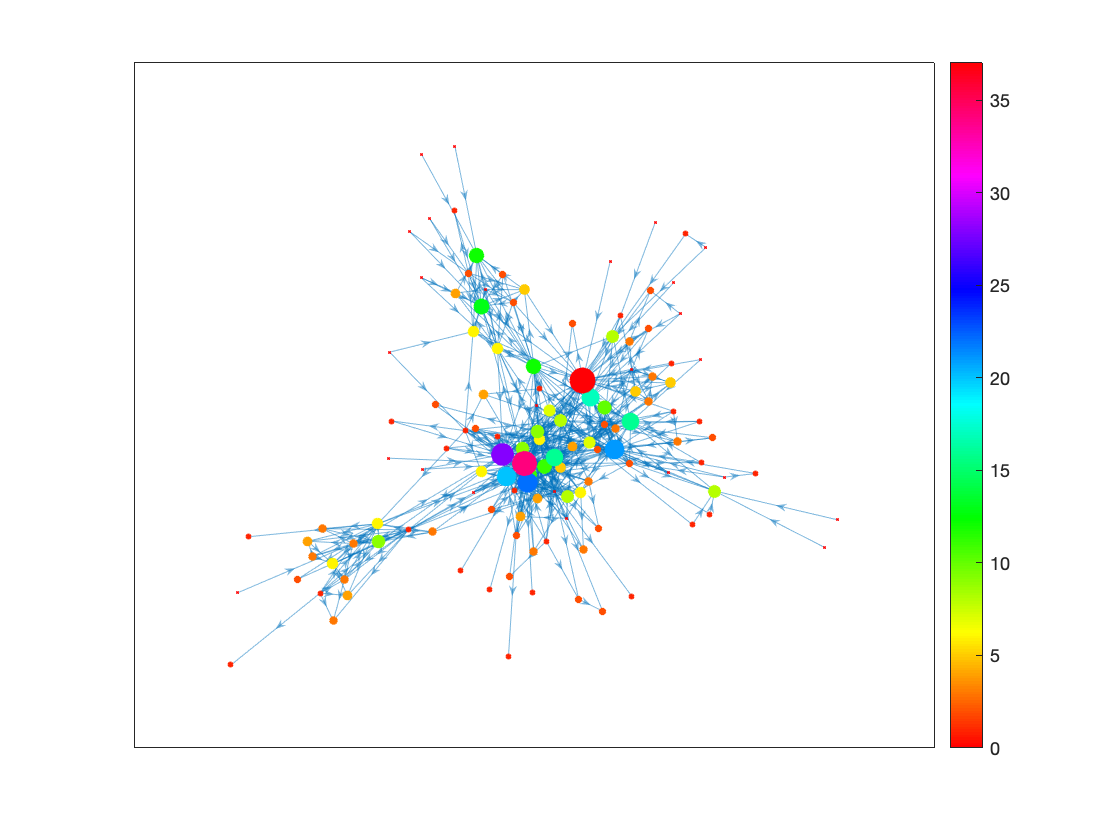

p =   GraphPlot with properties:

     NodeColor: 'flat'
    MarkerSize: [1×126 double]
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [1×126 double]
         YData: [1×126 double]
         ZData: [1×126 double]

  Show all properties


p.MarkerSize = k


Mini = table(G.Nodes.Name, D, 'VariableNames',{'Sources','Degree'})

Mini = 126×2 table
        Sources         Degree
    ________________    ______

    {'NED'         }      34  
    {'ROBERT'      }      28  
    {'DAENERYS'    }       1  
    {'JORAH'       }       6  
    {'JON'         }      12  
    {'SAM'         }      12  
    {'LITTLEFINGER'}      11  
    {'VARYS'       }      20  
    {'DROGO'       }       3  
    {'ARYA'        }       0  
    {'CATELYN'     }       7  
    {'ROBB'        }      21  
    {'BRONN'       }       0  
    {'TYRION'      }      37  
    {'CERSEI'      }       6  
    {'SHAE'        }       1  


Mini1 = sortrows(Mini, 'Degree', 'descend')

Mini1 = 126×2 table
        Sources         Degree
    ________________    ______

    {'TYRION'      }      37  
    {'NED'         }      34  
    {'ROBERT'      }      28  
    {'SANSA'       }      22  
    {'ROBB'        }      21  
    {'VARYS'       }      20  
    {'TYWIN'       }      17  
    {'THEON'       }      16  
    {'YOREN'       }      16  
    {'PYP'         }      13  
    {'JON'         }      12  
    {'SAM'         }      12  
    {'LITTLEFINGER'}      11  
    {'RENLY'       }      11  
    {'RODRIK'      }      10  
    {'JOFFREY'     }       9  


head(Mini1,5)

ans = 5×2 table
     Sources      Degree
    __________    ______

    {'TYRION'}      37  
    {'NED'   }      34  
    {'ROBERT'}      28  
    {'SANSA' }      22  
    {'ROBB'  }      21  
